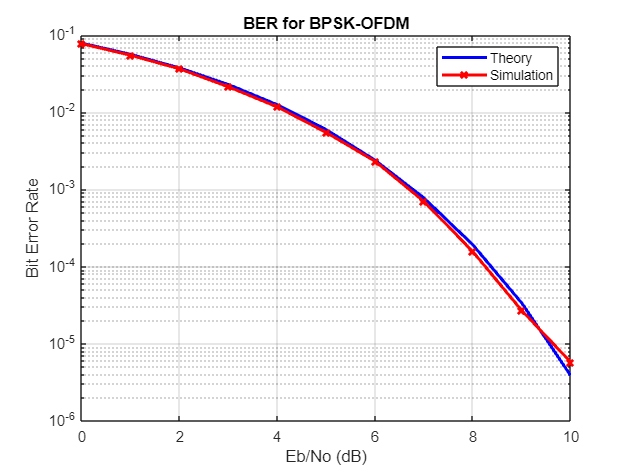

clear; close all;

% Parameters
nFFT = 64; nDSC = 52; nSym = 1e4;  
EbN0dB = 0:10;  
EsN0dB = EbN0dB + 10*log10(nDSC/nFFT) + 10*log10(80/64); 

nErr = zeros(1, length(EbN0dB)); % Initialize error counter

for ii = 1:length(EbN0dB)
    % Transmitter
    bits = randi([0 1], nDSC, nSym);  
    symbols = 2*bits - 1;  % BPSK Mapping

    % OFDM Modulation
    X = zeros(nFFT, nSym);
    X([7:32, 34:59], :) = symbols;  
    xt = ifft(X, nFFT) * sqrt(nFFT);  % Normalize power
    xt = [xt(end-15:end, :); xt];  % Add cyclic prefix

    % AWGN Channel
    noise = (randn(size(xt)) + 1i*randn(size(xt))) / sqrt(2); 
    yt = xt + 10^(-EsN0dB(ii)/20) * noise;  

    % Receiver
    yt = yt(17:end, :);  % Remove cyclic prefix
    Y = fft(yt, nFFT) / sqrt(nFFT);  % Normalize FFT
    bits_rx = real(Y([7:32, 34:59], :)) > 0;  

    % Count Errors
    nErr(ii) = sum(bits_rx(:) ~= bits(:));
end

% Compute BER
simBer = nErr / (nSym * nDSC);
theoryBer = (1/2) * erfc(sqrt(10.^(EbN0dB/10)));

% Plot BER
semilogy(EbN0dB, theoryBer, 'b-', 'LineWidth', 2);
hold on;
semilogy(EbN0dB, simBer, 'rx-', 'LineWidth', 2);
grid on; legend('Theory', 'Simulation');
xlabel('Eb/No (dB)'); ylabel('Bit Error Rate');
title('BER for BPSK-OFDM');